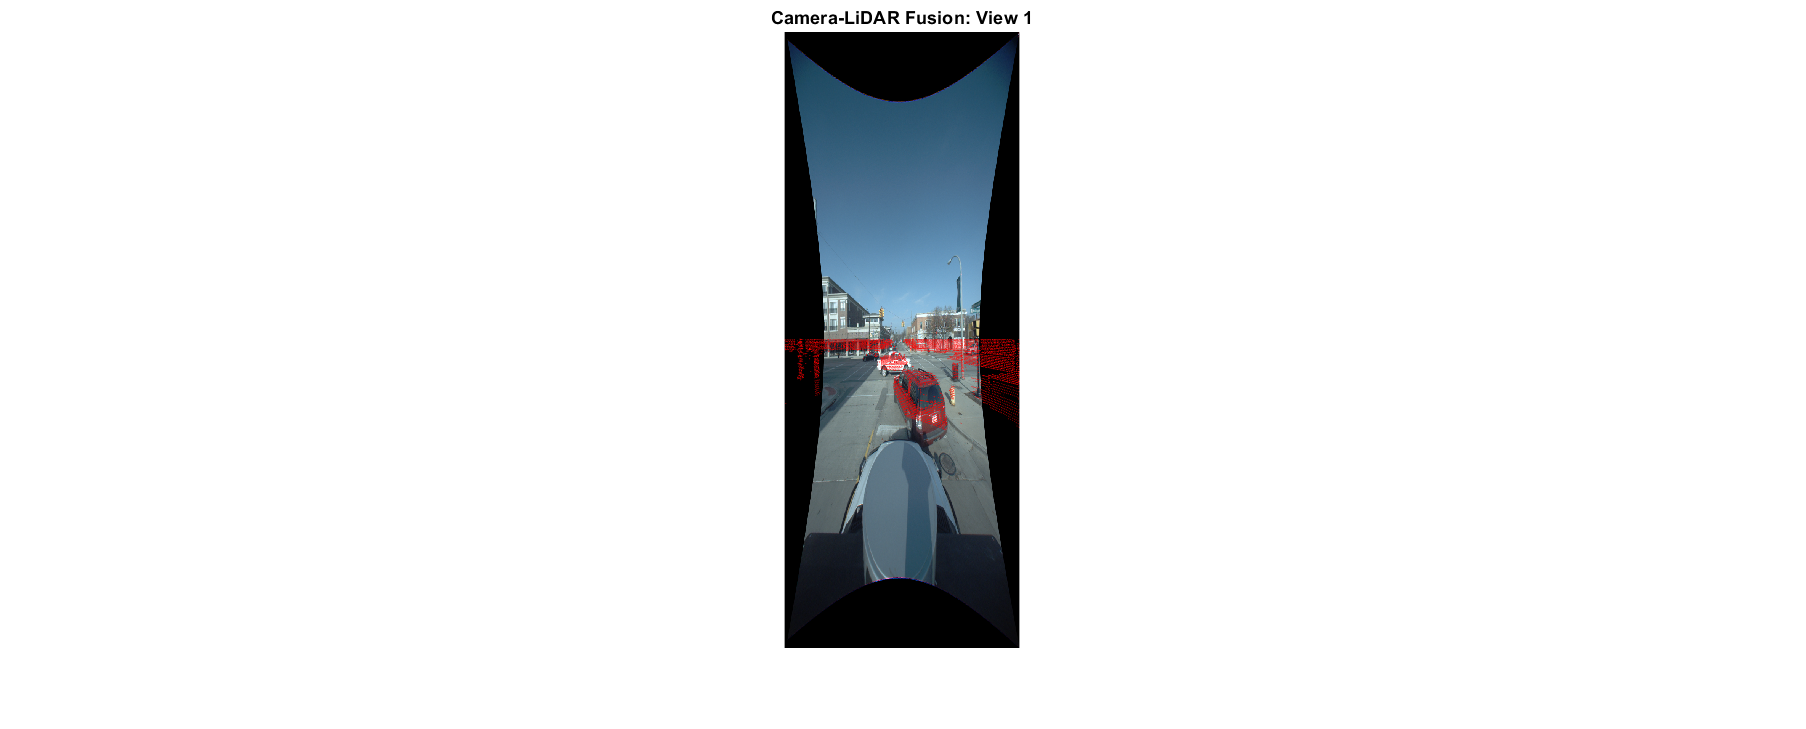

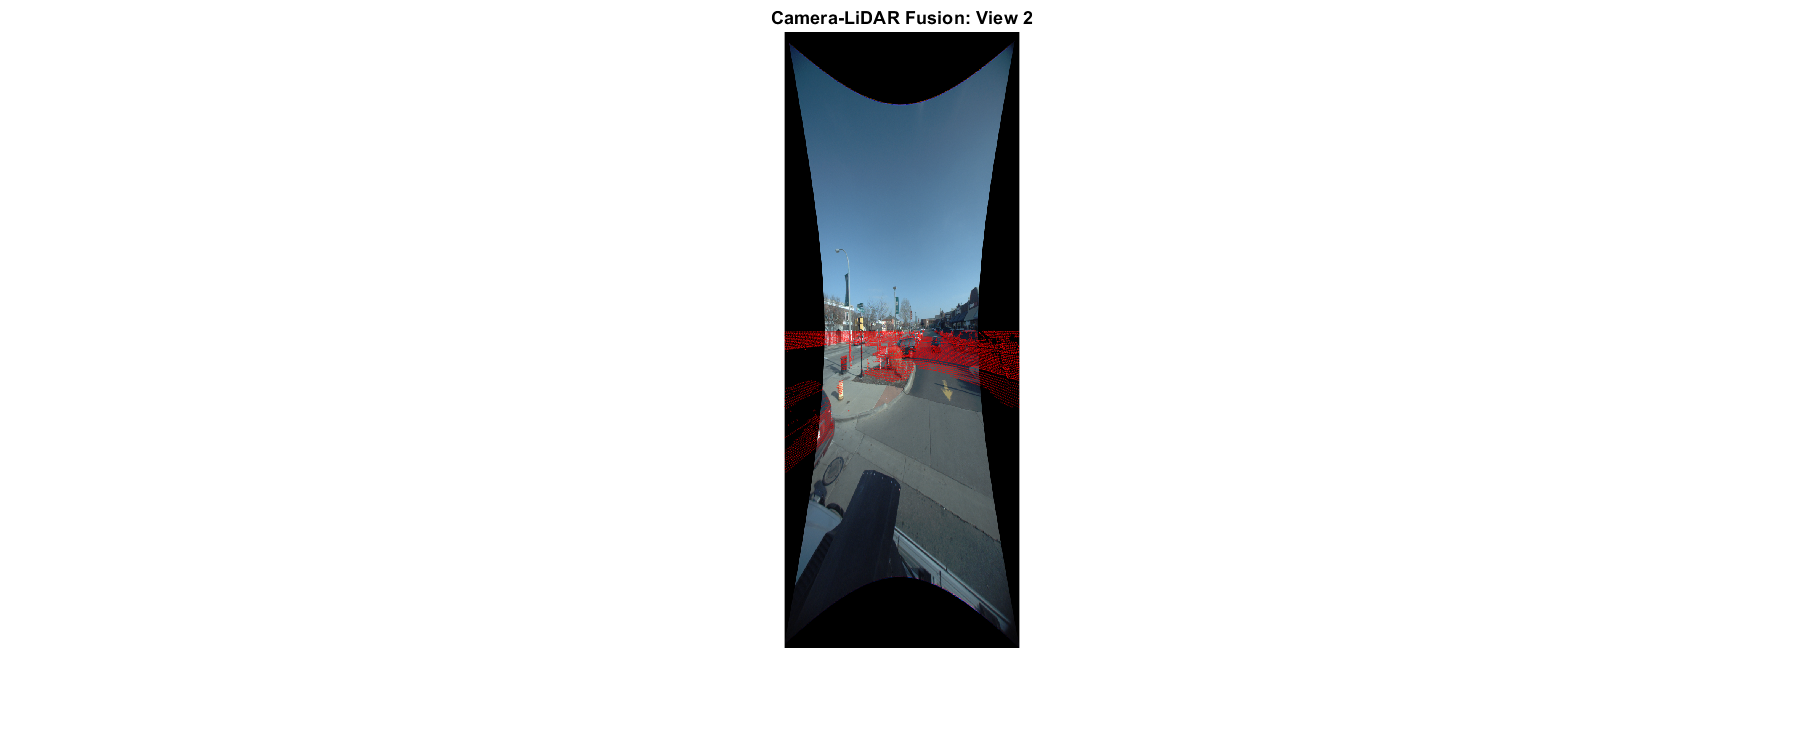

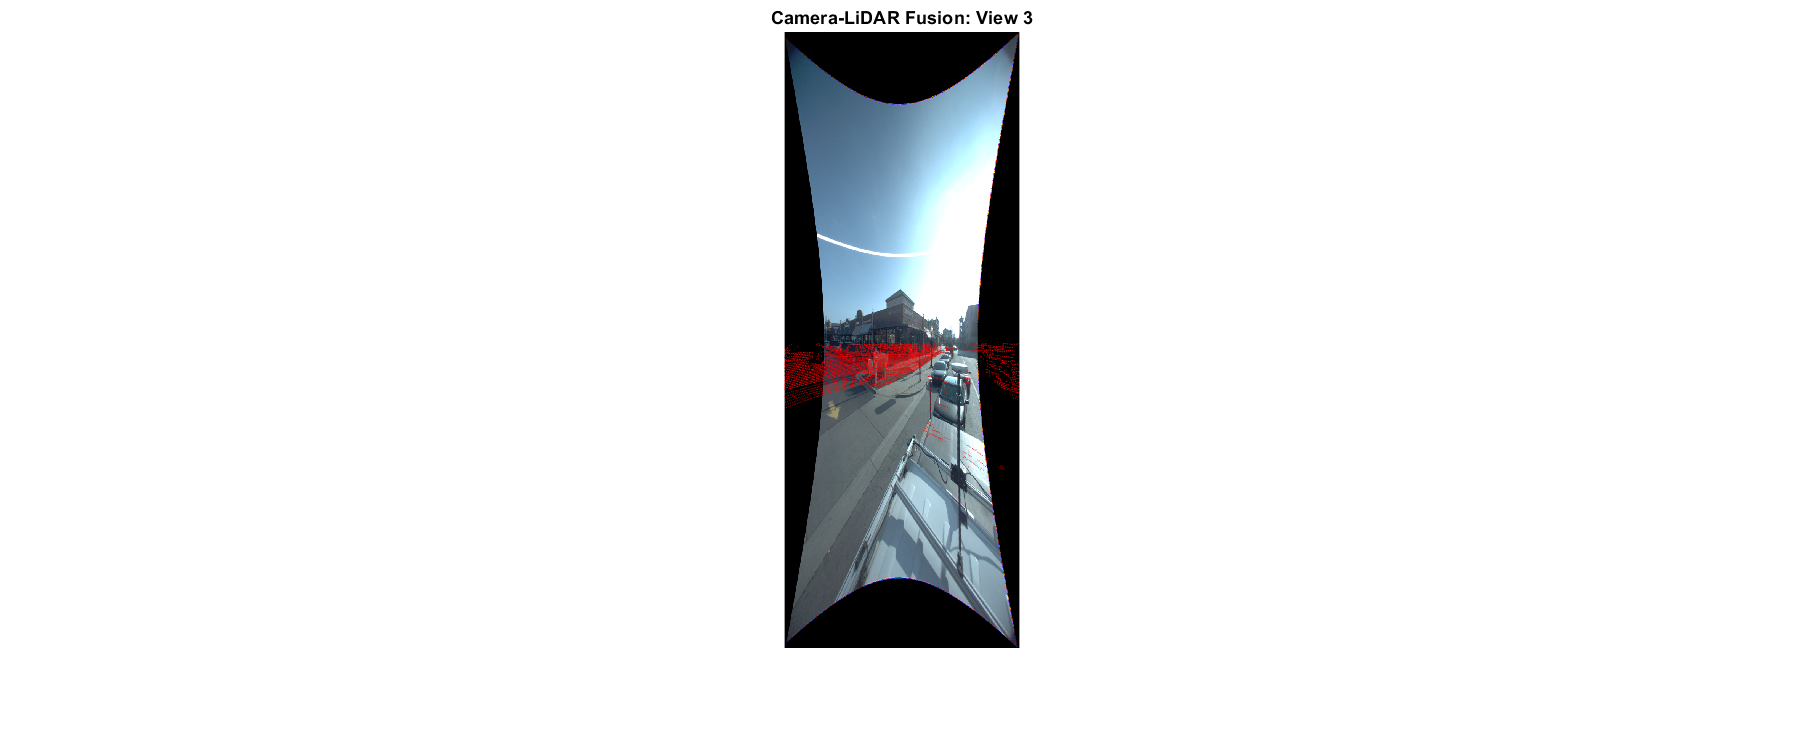

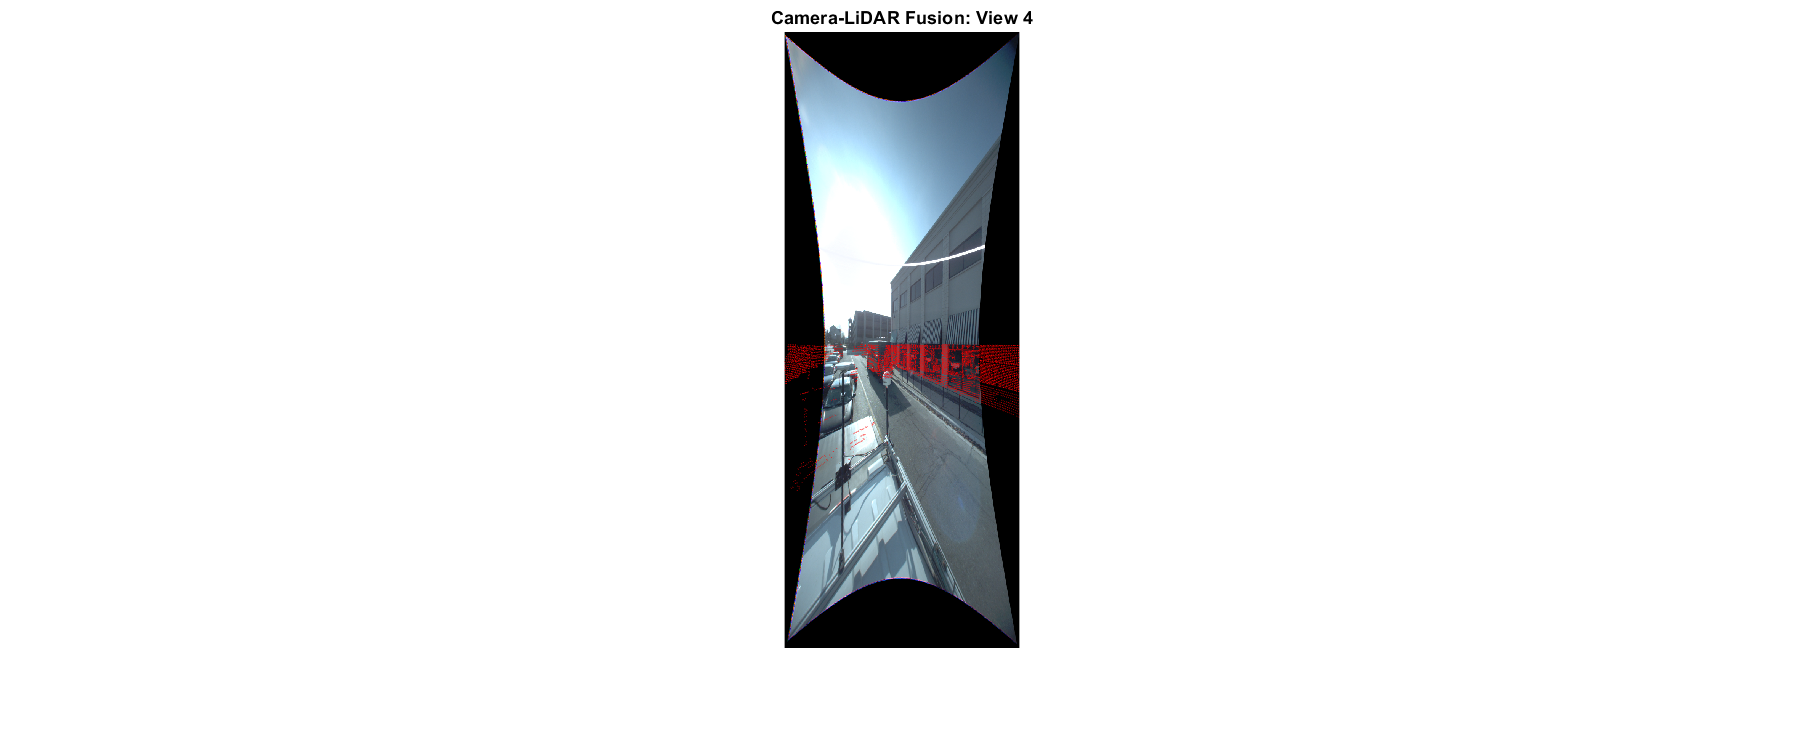

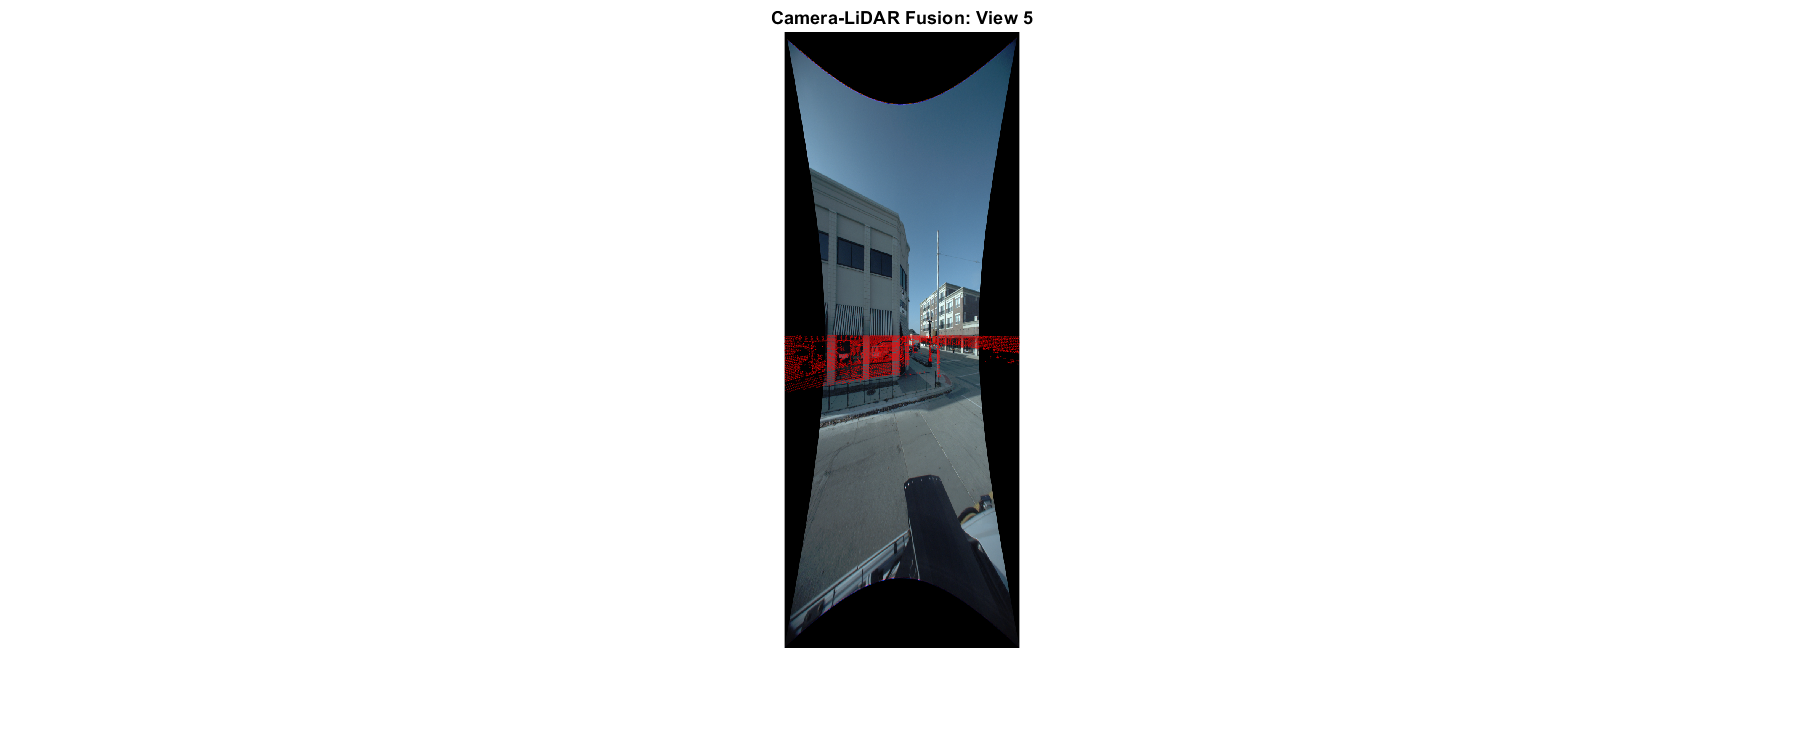

data = load('Problem.mat');
data = data.Problem;

% Transformation of lidar points to camera coordinate system
% Computing homogenous transformation matrix of Lidar corrdinate
% system [L] to camera reference frame [H]
Th = lidarTransformation(data.X_hl);

% Computing the inverse transformation matrix of Camera coordinate
% system [C] to camera reference frame [H] for all the cameras
Th_camera = cameraTransformation(data.X_hc);

% Computing the cumulative transformation matrice
% R_lc = inv(R_ch)*R_hl
T_total = Th_camera*Th;
lidar_scan = [transpose(data.scan);ones(1,length(data.scan))];
lidar_lc = T_total*lidar_scan;

for i=1:5
    % Extracting the lidar points in the coordinate frame of
    % camera 'i' from lidar_lc
    k = (i-1)*4+1;
    lidarScan = lidar_lc(k:k+2,:);
    
    % Initializing the intrinsic matrix for camera 'i'
    intrinsic_matrix = cell2mat(struct2cell(data.K(i)));
    
    % Storing the processed lidar scans in pixel 2D frame.
    final_lidar = pixelTransformation(intrinsic_matrix,lidarScan);
    
    % Displaying the lidar scan calibrated on the image
    figure
    imshow(cell2mat(struct2cell(data.Image(i))));
    hold on
    scatter(final_lidar(1,:),final_lidar(2,:),0.4,'r','filled');
    camroll(270)
    title(['Camera-LiDAR Fusion: View ' num2str(i)]);
    
end

function [processed_lidar] = pixelTransformation(intrinsic_matrix, lidarScan)
    % Filtering out the points infront of the camera
    lidar_lc1 = lidarScan;
    index = find(lidar_lc1(3,:)>0);
    lidar_lc1 = lidar_lc1(:,index);

    % Filtering out the points above the ground and at max 2.5 meters
    % above the ground
    index = find(lidar_lc1(1,:)>0 & lidar_lc1(1,:)<2.5);
    lidar_lc1 = lidar_lc1(:,index);
    
    % Converting these lidar points to pixel coordinate frame
    % The final points shall be in the homogenous 2D coordinate system
    lidar_lc1 = intrinsic_matrix*lidar_lc1;
    
    % Converting the homogenous coordinate into cartesian system
    lidar_lc1 = lidar_lc1./lidar_lc1(3,:);
    processed_lidar = lidar_lc1(1:2,:);
end

function [lidarScan] = lidarTransformation(lidar_params)
    ahl = deg2rad(lidar_params(1,4:6));
    Rz = [cos(ahl(1,3)), -sin(ahl(1,3)), 0; sin(ahl(1,3)), cos(ahl(1,3)), 0;0,0,1];
    Ry = [cos(ahl(1,2)),0,sin(ahl(1,2)); 0,1,0; -sin(ahl(1,2)),0, cos(ahl(1,2))];
    Rx = [1,0,0;0,cos(ahl(1,1)), -sin(ahl(1,1)); 0, sin(ahl(1,1)), cos(ahl(1,1))];
    R = [Rz*Ry*Rx;0,0,0];
    T = [lidar_params(1,1);lidar_params(1,2);lidar_params(1,3);1];
    lidarScan = [R,T];
end

function [cameraMatrices] = cameraTransformation(camera_pose)
    Th_camera = zeros(20,4);
    for i = 1:5
        camera_params = cell2mat(struct2cell(camera_pose(i)));
        ahc = deg2rad(camera_params(1,4:6));
        Rz = [cos(ahc(1,3)), -sin(ahc(1,3)), 0; sin(ahc(1,3)), cos(ahc(1,3)), 0;0,0,1];
        Ry = [cos(ahc(1,2)),0,sin(ahc(1,2)); 0,1,0; -sin(ahc(1,2)),0, cos(ahc(1,2))];
        Rx = [1,0,0;0,cos(ahc(1,1)), -sin(ahc(1,1)); 0, sin(ahc(1,1)), cos(ahc(1,1))];
        R = Rz*Ry*Rx;
        T = -transpose(R)*[camera_params(1,1);camera_params(1,2);camera_params(1,3)];
        T = [[transpose(R);0,0,0],[T;1]];
        j = (i-1)*4 + 1;
        Th_camera(j:j+3,:) = T;
    end
    cameraMatrices = Th_camera;
end